# **Pràctica 1: Anàlisi de la Resposta Temporal d'un Sistema de Control Digital**

Les pràctiques de l’assignatura control amb computador consisteixen en l’estudi d’un servomecanisme de posicionament angular controlat per un PC. Les sessions de laboratori P1 i P2 es centren, respectivament, en l’anàlisi experimental de les respostes temporal i freqüencial del sistema. Les sessions P3 i P4 es dediquen al disseny de controladors PID. Finalment, en la pràctica P5 es dissenyaran controladors en camp freqüencial.

**OBJECTIU: Anàlisi de la resposta temporal d'un sistema de control digital per a diferents períodes de mostratge. Anàlisi de la precisió i de l'estabilitat.**

**En esta sesión el estudiante ha de:**

- **Familiaritzar-se amb el sistema: amb la planta de temps continu i amb l’´us del computador com a generador de senyals, oscil·loscopi i controlador digital.**

- **Avaluar les prestacions (precisió i estabilitat) del sistema en funció del període de mostratge.**

% Canvi entre les dades de l'experiment i els del directori Resultats
% Si voleu utilitzar les dades del directori Resultats = false
% Si voleu utilitzar dades pròpies = true
useExperimentalData = false;

# Exercici 1: Resposta del sistema en llaç obert per al senyal del tacòmetre.

Obrir i executar el model P1_Ex1.slx. Comprovar que és la resposta típica d'un sistema de primer ordre i com varia el guany estàtica si apliquem al motor el fre magnètic. Identifiqueu la constant de temps $\tau_0$ i el guany estàtic $K_0$ per a una entrada graó de 1V. 

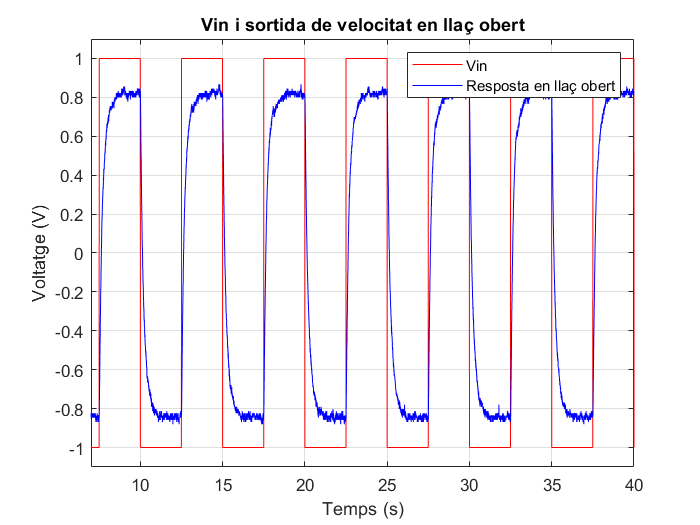

% Inicialització de variables
Tg=0.005; % Temps de graficació [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

% Dibuixar la resposta del motor
if useExperimentalData
    % Utilitzar Simulink
    addpath([pwd filesep 'E1']);
    open P1_Ex1.slx;
    run P1_Ex1.slx;
else
    FileName   = 'OpenLoopResponse.mat';
    cd('..')
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex1'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

figure
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,1,:)],'r')
hold on
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,2,:)],'b')
xlim([7 40]); ylim([-1.1 1.1]);
grid on
xlabel('Temps (s)');
ylabel('Voltatge (V)');
title('Vin i sortida de velocitat en llaç obert');
legend('Vin','Resposta en llaç obert');

% Aplicació del fre en llaç obert
if useExperimentalData
    % Utilitzar Simulink 
    addpath([pwd filesep 'E1']);
    open P1_Ex1.slx;
    run P1_Ex1.slx;
else
    FileName   = 'OpenLoopBrake.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex1'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

Com podem veure, la sortida s'assembla a la resposta d'un sistema de primer ordre sent la següent l'estructura de la seva funció de transferència.


$$\frac{V_{\mathrm{out}} \left(s\right)}{V_{\mathrm{in}} \left(s\right)}=\frac{k}{\tau s+1}$$


Per a aquest cas pràctic s'ha obtingut la següent funció de transferència.


$$\frac{V_{\textrm{out}} \left(s\right)}{V_{\textrm{in}} \left(s\right)}=\frac{0\ldotp 82}{0\ldotp 26s+1}$$


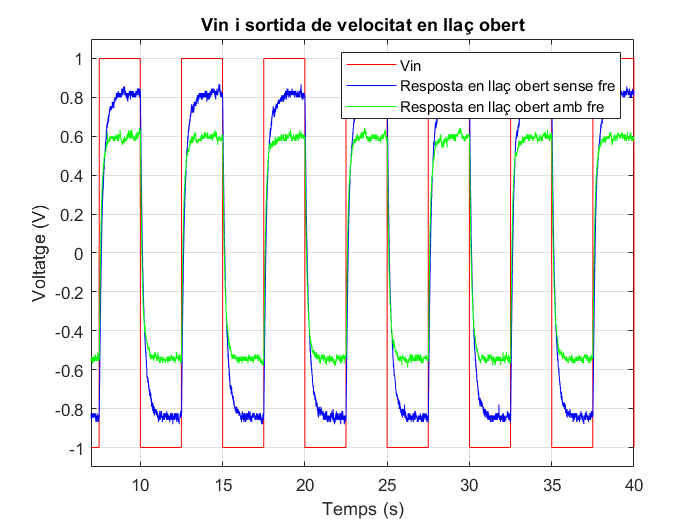

figure
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,1,:)],'r')
hold on
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,2,:)],'b')
plot(OpenLoopBrake.time,[OpenLoopBrake.signals.values(:,2,:)],'g')
xlim([7 40]); ylim([-1.1 1.1]);
grid on
xlabel('Temps (s)');
ylabel('Voltatge (V)');
title('Vin i sortida de velocitat en llaç obert');
legend('Vin','Resposta en llaç obert sense fre','Resposta en llaç obert amb fre');

D'altra banda, en el cas de llaç obert, aquest guany varia depenent del fre. Com es pot veure a la imatge, si apliquem el fre, el guany es reduirà considerablement.

# Exercici 2: Resposta del sistema en llaç tancat amb realimentació de velocitat.

Obrir i executar el model P1_Ex2.slx. Comprovar com varia l'error en estat estacionari per Kp= 1, 2 y 5, canviant el bloc "Controlador Proporcional".

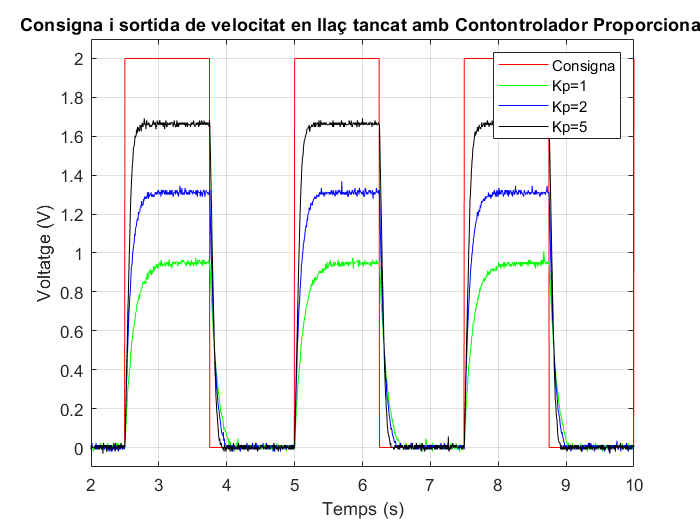

% Inicialització de variables
Tg=0.005; % Temps de graficació [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

if useExperimentalData
    % Utilitzar Simulink 
    addpath([pwd filesep 'E2']);
    open P1_Ex2.slx;
    run P1_Ex2.slx;
else % Carregar variables
    FileName   = 'Kp1.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex2'];
  %  FolderName = [pwd filesep '..' filesep '..' filesep 'Resultados' filesep 'Prac1' filesep 'Ex2'];
    File       = fullfile(FolderName, FileName);
    load(File); 
    
    FileName   = 'Kp2.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex2'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Kp5.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex2'];
    File       = fullfile(FolderName, FileName);
    load(File); 
end


% senyals de sortida
figure
plot(Kp1.time,[Kp1.signals.values(:,3,:)],'r') 
hold all
plot(Kp1.time, [Kp1.signals.values(:,1,:)],'g')
plot(Kp2.time, [Kp2.signals.values(:,1,:)],'b')
plot(Kp5.time, [Kp5.signals.values(:,1,:)],'k')
xlim([2 10]); ylim([-0.1 2.1]);
grid on
xlabel('Temps (s)');
ylabel('Voltatge (V)');
title('Consigna i sortida de velocitat en llaç tancat amb Contontrolador Proporcional');
legend('Consigna','Kp=1','Kp=2','Kp=5');

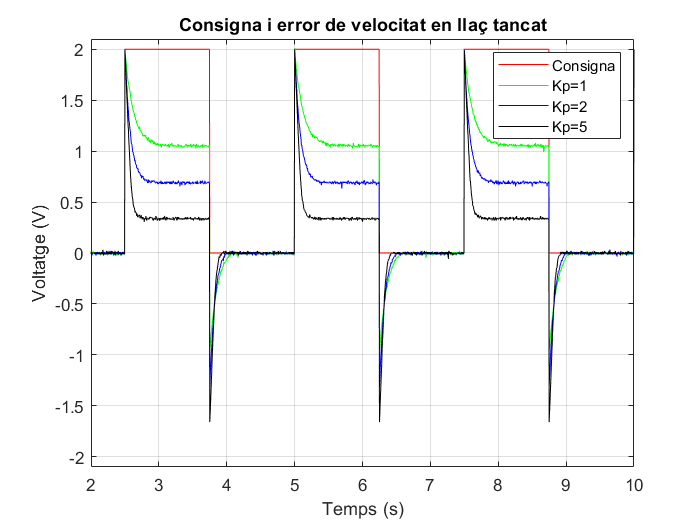

% senyals d'error
figure
plot(Kp1.time,[Kp1.signals.values(:,3,:)],'r') 
hold all
plot(Kp1.time, [Kp1.signals.values(:,2,:)],'g')
plot(Kp2.time, [Kp2.signals.values(:,2,:)],'b')
plot(Kp5.time, [Kp5.signals.values(:,2,:)],'k')
xlim([2 10]); ylim([-2.1 2.1]);
grid on;
xlabel('Temps (s)');
ylabel('Voltatge (V)');
title('Consigna i error de velocitat en llaç tancat');
legend('Consigna','Kp=1','Kp=2','Kp=5');

Com es pot veure en les imatges anteriors, a major Kp, la resposta és més ràpida i l'error en estat estacionari menor.

# Exercici 3: Avaluació experimental de les prestacions del sistema en llaç tancat amb realimentació de velocitat. 

Obrir i executar el model P1_Ex3.slx. Avaluar com varia la precisió i l'estabilitat del sistema per a diferents períodes de mostratge.

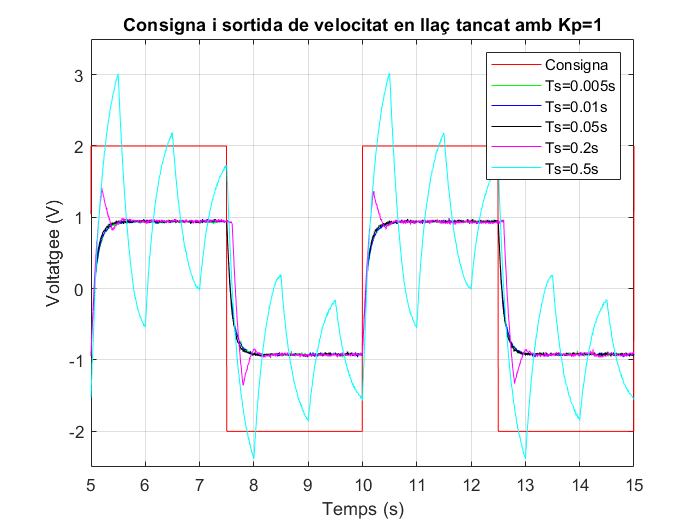

% Inicialització de variables
Tg= 0.005; % Temps de graficació [seg]
Ts=0.01; % Període de mostratge
Vmax=5; % [V]
Vmin=-5; % [V]

if useExperimentalData
    % Utilitzar Simulink 
    addpath([pwd filesep 'E3']);
    open P1_Ex3.slx;
    run P1_Ex3.slx;
else % Carregar variables
    FileName   = 'Ts5ms.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex3'];
    File       = fullfile(FolderName, FileName);
    load(File);   

    FileName   = 'Ts10ms.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex3'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Ts50ms.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex3'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Ts02s.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex3'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Ts05s.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex3'];
    File       = fullfile(FolderName, FileName);
    load(File);
end


% sortida
figure()
plot(Ts5ms.time,[Ts5ms.signals.values(:,2,:)],'r')
hold all
plot(Ts5ms.time, [Ts5ms.signals.values(:,3,:)],'g')
plot(Ts10ms.time, [Ts10ms.signals.values(:,3,:)],'b')
plot(Ts50ms.time, [Ts50ms.signals.values(:,3,:)],'k')
plot(Ts02s.time, [Ts02s.signals.values(:,3,:)],'m')
plot(Ts05s.time, [Ts05s.signals.values(:,3,:)],'c')
xlim([5 15]);ylim([-2.5 3.5]);
grid on;
xlabel('Temps (s)');
ylabel('Voltatgee (V)');
title('Consigna i sortida de velocitat en llaç tancat amb Kp=1');
legend('Consigna','Ts=0.005s','Ts=0.01s','Ts=0.05s','Ts=0.2s','Ts=0.5s')

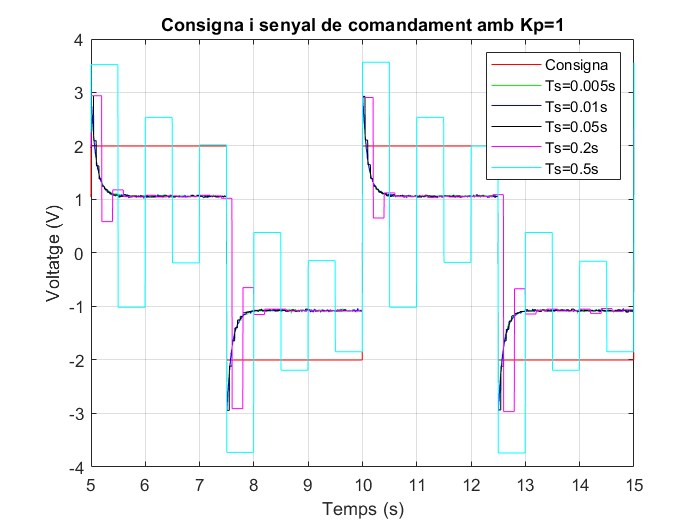

% error
figure()
plot(Ts5ms.time,[Ts5ms.signals.values(:,2,:)],'r')
hold all
plot(Ts5ms.time, [Ts5ms.signals.values(:,1,:)],'g')
plot(Ts10ms.time, [Ts10ms.signals.values(:,1,:)],'b')
plot(Ts50ms.time, [Ts50ms.signals.values(:,1,:)],'k')
plot(Ts02s.time, [Ts02s.signals.values(:,1,:)],'m')
plot(Ts05s.time, [Ts05s.signals.values(:,1,:)],'c')
xlim([5 15]);ylim([-4 4]);
grid on;
xlabel('Temps (s)');
ylabel('Voltatge (V)');
title('Consigna i senyal de comandament amb Kp=1');
legend('Consigna','Ts=0.005s','Ts=0.01s','Ts=0.05s','Ts=0.2s','Ts=0.5s')

Per analitzar a partir que Ts tindrem oscil·lacions, cal obtenir la funció de transferència digital de llaç tancat. Per a això, primerament, es calcularà la funció de transferència digital de llaç obert usant per a això un mantenidor d'ordre zero. 


$$\mathrm{llaç}\;\mathrm{obert}:\;L\left(z\right)=Z\left\lbrace k_p G_{\textrm{mot}} \left(s\right)G_{\textrm{zoh}} \left(s\right)\right\rbrace =Z\left\lbrace k_p ·\frac{k_{\textrm{mot}} k_{\textrm{tac}} }{\tau_{\textrm{mot}} s+1}·\frac{1-e^{-T_s ·s} }{s}\right\rbrace =k_p k_{\textrm{mot}} k_{\textrm{tac}} \frac{1-\alpha }{z-\alpha }$$



$$\mathrm{llaç}\;\mathrm{tancat}:G\left(z\right)=\frac{L\left(z\right)}{1+L\left(z\right)}=\frac{k_p k_{\textrm{mot}} k_{\textrm{tac}} \left(1-\alpha \right)}{z-\alpha +k_p k_{\textrm{mot}} k_{\textrm{tac}} \left(1-\alpha \right)}\;\;\;\;\;\;\textrm{where}\;\;\;\;\;\;\;\;\alpha =e^{\frac{-\textrm{Ts}}{\tau_{\textrm{mot}} }}$$



$$\textrm{pols}:p={-k}_p k_{\textrm{mot}} k_{\textrm{tac}} -\left(1+k_p k_{\textrm{mot}} \right)e^{\frac{-\textrm{Ts}}{\tau_{\textrm{mot}} }} =0$$



$$T_s =\tau_{\mathrm{mot}} ·\mathrm{ln}\left|\frac{1+k_p k_{\mathrm{mot}} k_{\mathrm{tac}} }{k_p k_{\mathrm{mot}} k_{\mathrm{tac}} }\right|$$


Un cop obtingut l'expressió de pol, la qual igualarem a zero, ja que el sistema comencés a oscil·lar en aquest precís moment. En aquest cas, avaluant l'equació amb els nostres paràmetres, obtenim que el sistema comencés a oscil·lar a 0.2 segons de temps de mostreig i com es pot veure a la imatge, la resposta del sistema amb aquest període de mostreig, la resposta de color magenta, presenta un sobre impuls. A majors temps de mostreig, la sortida és encara més oscil·lant. 

# Exercici 4: Resposta del sistema en llaç obert per al senyal del potenciòmetre.

Obrir i executar el model P1_Ex4.slx. Comprovar que és la resposta típica d'un sistema de tipus 1. 

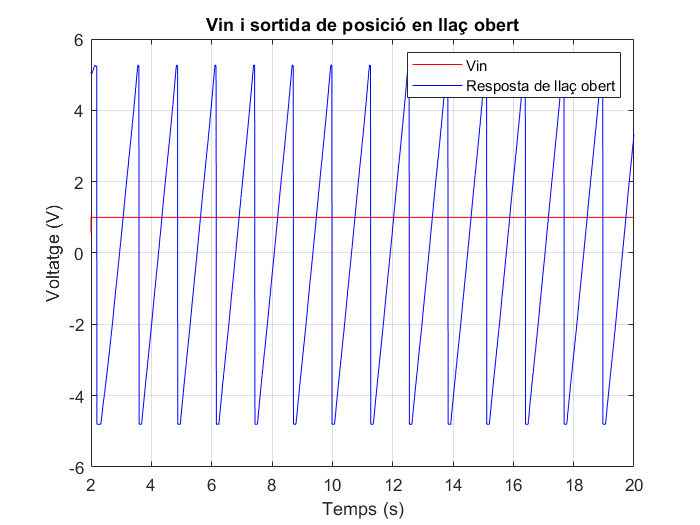

% Inicialització de variables
Tg=0.005; % Temps de graficació [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

if useExperimentalData
    % Utilitzar Simulink 
    addpath([pwd filesep 'E4']);
    open P1_Ex4.slx
    run P1_Ex4.slx
else % Carregar resposta llaç obert
    FileName   = 'OpenLoopPosition.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex4'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

% sortida
figure
plot(OpenLoopPosition.time,[OpenLoopPosition.signals.values(:,1,:)],'r')
hold on
plot(OpenLoopPosition.time,[OpenLoopPosition.signals.values(:,2,:)],'b')
xlim([2 20]);grid on;
xlabel('Temps (s)');
ylabel('Voltatge (V)');
title('Vin i sortida de posició en llaç obert');
legend('Vin','Resposta de llaç obert ');

En aquest cas, la resposta de la planta en llaç obert és un senyal periòdic amb forma d'ona de serra, ja que la planta és de tipus 1. Amb la qual cosa, a entrades tipus graó obtindrem un senyal tipus rampa. D'altra banda, la periodicitat passa per cada volta de l'eix del potenciòmetre.

# Exercici 5: Resposta del sistema en llaç tancat amb realimentació de posició.

Obrir i executar el model P1_Ex5.slx. Comprovar com varia l'error en estat estacionari per a Kp= 1, 2 y 3, canviant el bloc "Proportional Controller".

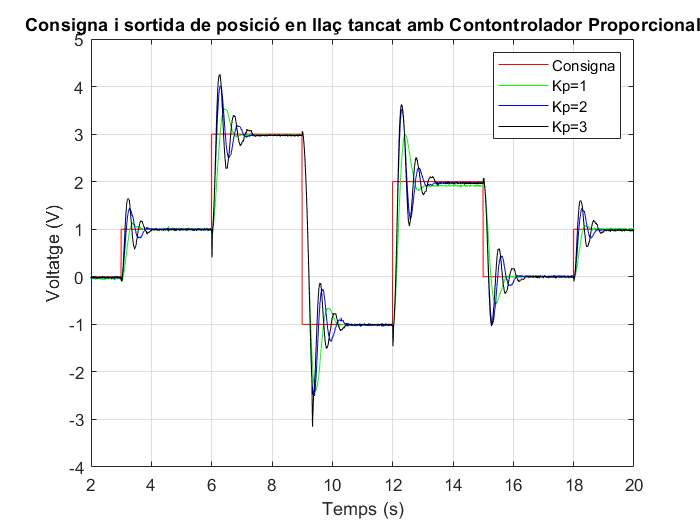

% Inicialització de variables
Tg=0.005; % Temps de graficació [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

if useExperimentalData
    % Utilitzar Simulink 
    addpath([pwd filesep 'E5']);
    open P1_Ex5.slx
    run P1_Ex5.slx
else % Carregar variables
    FileName   = 'Kp1.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex5'];
    File       = fullfile(FolderName, FileName);
    load(File);   
    
    FileName   = 'Kp2.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex5'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Kp3.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex5'];
    File       = fullfile(FolderName, FileName);
    load(File);
end

% sortida
figure
plot(Kp1.time,[Kp1.signals.values(:,3,:)],'r') 
hold all; grid on;
plot(Kp1.time, [Kp1.signals.values(:,1,:)],'g')
plot(Kp2.time, [Kp2.signals.values(:,1,:)],'b')
plot(Kp3.time, [Kp3.signals.values(:,1,:)],'k')
xlim([2 20]);
xlabel('Temps (s)');
ylabel('Voltatge (V)');
title('Consigna i sortida de posició en llaç tancat amb Contontrolador Proporcional');
legend('Consigna','Kp=1','Kp=2','Kp=3');

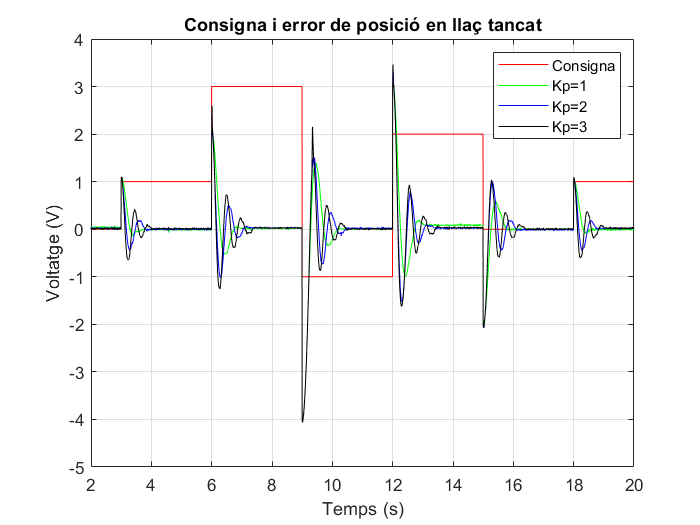

% error
figure
plot(Kp1.time,[Kp1.signals.values(:,3,:)],'r') 
hold all; grid on;
plot(Kp1.time, [Kp1.signals.values(:,2,:)],'g')
plot(Kp2.time, [Kp2.signals.values(:,2,:)],'b')
plot(Kp3.time, [Kp3.signals.values(:,2,:)],'k')
xlim([2 20]);
xlabel('Temps (s)');
ylabel('Voltatge (V)');
title('Consigna i error de posició en llaç tancat');
legend('Consigna','Kp=1','Kp=2','Kp=3');

En aquest cas, com el motor és de tipus 1, l'error estacionari serà zero, però el sobre impuls i el temps d'establiment variaran depenent del guany del controlador. A més Kp, més gran és el sobre impuls i major el temps d'establiment.

# Exercici 6: Avaluació experimental de les prestacions del sistema en llaç tancat amb realimentació de posició. 

Obrir i executar el model P1_Ex6.slx. Avaluar com varia la precisió i l'estabilitat del sistema per a diferents períodes de mostratge.

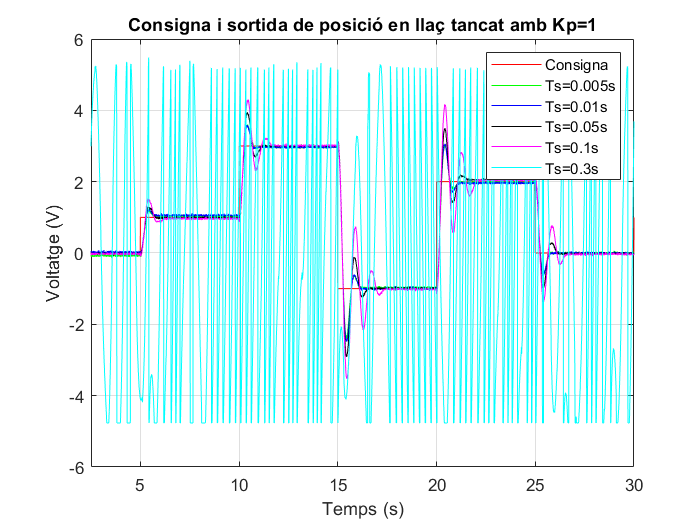

% Inicialització de variables
Tg= 0.005; % Temps de graficació [seg]
Ts=0.01; % Període de mostratge
Vmax=5; % [V]
Vmin=-5; % [V]

if useExperimentalData
    % Utilitzar Simulink 
    addpath([pwd filesep 'E6']);
    open P1_Ex6.slx
    run P1_Ex6.slx
else % Carregar variables
    FileName   = 'Ts005.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex6'];
    File       = fullfile(FolderName, FileName);
    load(File);   
    
    FileName   = 'Ts01.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex6'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Ts05.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex6'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Ts1.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex6'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Ts3.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex6'];
    File       = fullfile(FolderName, FileName);
    load(File);
end

% sortida
figure
plot(Ts005.time, [Ts005.signals.values(:,2,:)],'r')
hold all; grid on;
plot(Ts005.time, [Ts005.signals.values(:,3,:)],'g')
plot(Ts01.time, [Ts01.signals.values(:,3,:)],'b')
plot(Ts05.time, [Ts05.signals.values(:,3,:)],'k')
plot(Ts1.time, [Ts1.signals.values(:,3,:)],'m')
plot(Ts3.time, [Ts3.signals.values(:,3,:)],'c')
xlim([2.5 30]);
xlabel('Temps (s)');
ylabel('Voltatge (V)');
title('Consigna i sortida de posició en llaç tancat amb Kp=1');
legend('Consigna','Ts=0.005s','Ts=0.01s','Ts=0.05s','Ts=0.1s','Ts=0.3s')

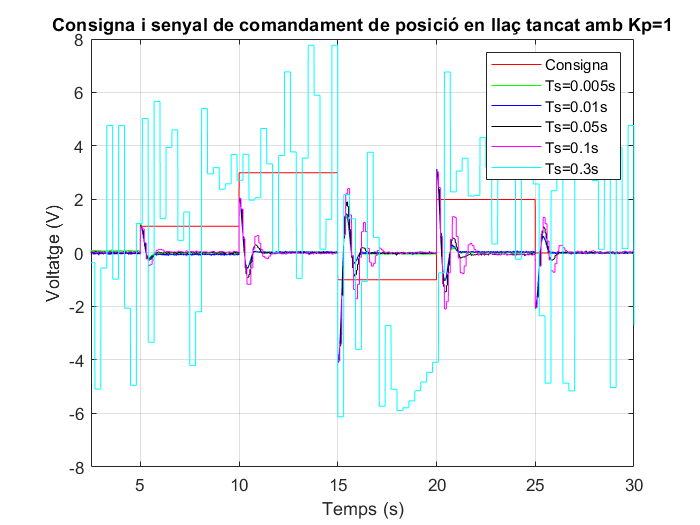

% error
figure
plot(Ts005.time, [Ts005.signals.values(:,2,:)],'r')
hold all; grid on;
plot(Ts005.time, [Ts005.signals.values(:,1,:)],'g')
plot(Ts01.time, [Ts01.signals.values(:,1,:)],'b')
plot(Ts05.time, [Ts05.signals.values(:,1,:)],'k')
plot(Ts1.time, [Ts1.signals.values(:,1,:)],'m')
plot(Ts3.time, [Ts3.signals.values(:,1,:)],'c')
xlim([2.5 30]);
xlabel('Temps (s)');
ylabel('Voltatge (V)');
title('Consigna i senyal de comandament de posició en llaç tancat amb Kp=1');
legend('Consigna','Ts=0.005s','Ts=0.01s','Ts=0.05s','Ts=0.1s','Ts=0.3s')

En aquest cas també, per analitzar a partir de quin valor el sistema es tornarà inestable, com hem fet anteriorment, s'ha digitalitzat la planta amb l'ajuda d'un mantenidor d'ordre zero, s'ha obtingut el model digital de llaç tancat i analitzat aquests pols. Avaluant el denominador mitjançant el criteri d'estabilitat de Jury, s'obté que el coix de Ts perquè el sistema sigui estable és de 0 a 0.3 segons.